% part B, manual

% u =[6,8,8,8,8,8,8,8,8,2
%     6,0,0,0,0,0,0,0,0,2
%     6,0,0,0,0,4,4,0,0,2
%     6,0,0,0,16,-1,-1,12,0,2
%     6,0,0,4,16,-1,-1,12,0,2
%     6,4,4,-1,-1,-1,-1,-1,4,2    
% ]
% 
% v =[6,8,8,8,8,8,8,8,8,2
%     6,0,0,0,0,0,0,0,0,2
%     6,0,0,0,0,4,4,0,0,2
%     6,0,0,0,16,-1,-1,12,0,2
%     6,0,0,4,16,-1,-1,12,0,2
%     6,4,4,-1,-1,-1,-1,-1,4,2    
% ]
% 
% p=[6,8,8,8,8,8,8,8,8,2
%     6,0,0,0,0,0,0,0,0,2
%     6,0,0,0,0,4,4,0,0,2
%     6,0,0,0,16,-1,-1,12,0,2
%     6,0,0,4,17,-1,-1,11,0,2
%     6,4,4,-1,-1,-1,-1,-1,4,2    
% ]
% 
% imagesc(u)
% imagesc(v)
% imagesc(p)

%%part C, programatically

N.x_u = 100;
N.y_u = 100;
N.x_v = 100;
N.y_v = 100;
N.x_p = 100;
N.y_p = 100;

u_type=zeros(N.x_u,N.y_u);
v_type=zeros(N.x_v,N.y_v);
p_type=zeros(Nxp,Nyp);

u_type(1,2:end-1) = 8;      %%Left&Right Overrule at Corners
u_type(end,2:end-1) = 4;
u_type(:,1) = 6;
u_type(:,end) = 2;

v_type(1,:) = 8;
v_type(end,:) = 4;
v_type(2:end-1,1) = 6;     %%Top&Bottom Overrule at Corners
v_type(2:end-1,end) = 2;

p_type(1,end)       = 1;
p_type(2:end-1,end) = 2;
p_type(end,end)     = 3;
p_type(end,2:end-1) = 4;
p_type(end,1)       = 5;
p_type(2:end-1,1)   = 6;
p_type(1,1)         = 7;
p_type(1,2:end-1)   = 8;


% Parameters
rise_slope = 1;
fall_slope = -1;
start_mountain = floor(Nxp*20/100)

start_mountain = 20

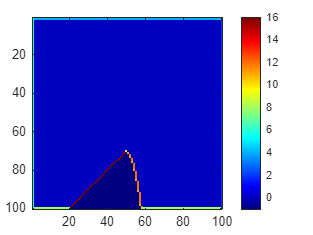

peak = floor(Nxp*50/100);
end_mountain = floor(Nxp*80/100);

% Left Side of Mountain
for i = start_mountain+1 : peak
    j = round(rise_slope * (i - start_mountain));
    if j <= N.y_u
        u_type(1:j, i) = -1;
    end
end

% Right Side Of Mountain
for i = peak+1 : end_mountain
    j = round(fall_slope * (i - peak) + j);  % continue from where rise ended
    if j >= 1 && j <= N.y_u
        u_type(1:j, i) = -1;
    end
end

%%%Boundary cells
for i = 1:N.y_u-1
    for j = 2:N.x_u-1
        if u_type(i,j) == 0
            below = u_type(i-1, j);
            above  = u_type(i+1, j);
            right = u_type(i, j+1);
            left  = u_type(i, j-1);            
            
            if below == -1 && left == -1
                u_type(i,j) = 11;
            elseif left == -1
                u_type(i,j) = 12;
            elseif above == -1 && left == -1
                u_type(i,j) = 13;    
            elseif above == -1
                u_type(i,j) = 14;
            elseif above == -1 && right == -1
                u_type(i,j) = 15;
            elseif right == -1
                u_type(i,j) = 16;
            elseif below == -1 && right == -1
                u_type(i,j) = 17;
            elseif below == -1
                u_type(i,j) = 10;
            
            end
        end
    end
end


imagesc(flipud(u_type));
colorbar;
colormap(jet)

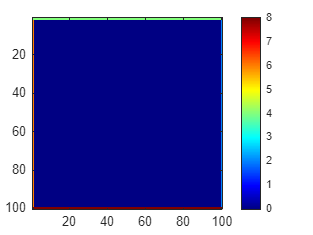

imagesc(flipud(v_type));
colorbar;
colormap(jet)

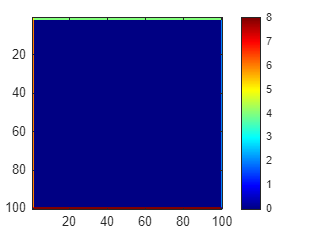


imagesc(flipud(p_type));
colorbar;
colormap(jet)